## Neuroseries Tutorial

by Luke Sjulson, 2020-06-22

Notes: 

1) before starting, go to the base directory of TStoolbox and run Make_TSToolbox.m in MATLAB. This will compile the mex files. 

2) launch this live script from the TStoolbox base directory 

3) hit "run" or F5 to run this live script before going through it. Some of the sections depend on the results from earlier sections, and they need to be run in order.

**Neuroseries toolbox** (formerly TStoolbox, for “Time Stamp”) is a class library for dealing with neurophysiological data in matlab (a python version also exists). Neuroseries is object-oriented, meaning that it is organized around objects instead of functions. An object is simply a struct where its associated functions are inside the struct instead of outside. This makes it easier to keep track of which functions work with which data types, as well as preventing confusion between different functions with the same name. Object-oriented programming (OOP) is the dominant paradigm in industry because it encourages code reusability by making code modular. More importantly, it forces you to do things in a certain way that simplifies things, makes code easier to read, and prevents you from making common mistakes.

In OOP, you start with “classes” and create “objects” from a particular class. Using Neuroseries requires you to understand a four different classes:

## 1) intervalSets. An intervalSet is an object containing a set of intervals, i.e. vectors of start and end times for each time interval. 

- This is used to store states of the animal or events that have a beginning and end. In OOP, to create an object from scratch you need to call a function called a “constructor”. In this case, the constructor is called IntervalSet(). For example:

% starting from TStoolbox base directory
cd('tutorial')

% a simple example indicating when the animal is in the left side of the
% box

% fake data
left_zone_entry_times  = [11000 11600 12200]'; % animal enters left half of box
left_zone_exit_times   = [11200 11900 12600]'; % animal enters left half of box

% calling the intervalSet constructor to generate a new
% intervalSet object to hold this data
in_left_IS      = intervalSet(left_zone_entry_times, left_zone_exit_times);
in_left_IS.name = 'animal in left side of box';

% or alternatively, use buzcode format with t x 2 matrix
in_left_IS      = intervalSet([left_zone_entry_times left_zone_exit_times]);
in_left_IS.name = 'animal in left side of box';

% to make this tutorial easier to understand, I will end
% the variable names with an abbreviation of the type of
% object, but you don't need to do that in real life
in_left_IS

in_left_IS =   intervalSet with properties:

    version: 2
      start: [11000 11600 12200]
       stop: [11200 11900 12600]
       name: 'animal in left side of box'


You can reference any field in the object as if it were a struct

in_left_IS.version

ans = 2

To access the methods for this object (i.e. the functions contained inside), type in_left. <tab> and it will bring up an autocomplete list. Here are some examples using a second intervalSet that indicates the time intervals when ripples are occurring in CA1:

load RipplesSleep.mat % a struct we use to keep track of ripples
% The RipplesSleep struct has a field .epoch, which contains 
% an intervalSet for times when ripples are occurring.
ripple_IS = RipplesSleep.epoch;

ripple_IS.name = 'ripples'; % this should have been in the mat file
ripple_IS

ripple_IS =   intervalSet with properties:

    version: 2
      start: [1×4192 double]
       stop: [1×4192 double]
       name: 'ripples'



% merging ripples closer than 0.1 seconds together
merged_ripples_IS = ripple_IS.mergeCloseIntervals(0.1)

merged_ripples_IS =   intervalSet with properties:

    version: 2
      start: [1×3886 double]
       stop: [1×3886 double]
       name: []



% dropping ripples shorter than 50 ms in duration
long_ripples_only_IS = ripple_IS.dropShortIntervals(0.05)

long_ripples_only_IS =   intervalSet with properties:

    version: 2
      start: [1×313 double]
       stop: [1×313 double]
       name: []


In OOP syntax of most languages, you call methods (internal functions) of objects with the syntax

new_IS = ripple_IS.dropShortIntervals(0.01);

In the obsolete MATLAB OOP syntax, it was

new_IS = dropShortIntervals(rippleIS, 0.01);

For this toolbox, you can use either, but the first version is encouraged because it is the new MATLAB syntax and is more consistent with Python and C++.

You can perform Boolean operations on pairs of intervalSets: for example, if you wanted to isolate only the ripples that occurred when the animal was in the left side of the box, make a new intervalSet

ripples_on_left_IS = in_left_IS & ripple_IS

ripples_on_left_IS =   intervalSet with properties:

    version: 2
      start: [1×23 double]
       stop: [1×23 double]
       name: []


% you can do union, intersection, etc. The & and | operators
% work, or you can use
% first_intervalSet.intersection(second_intervalSet)


Or if you wanted to look only at ripples that occurred when the animal was NOT in the left side

ripples_not_on_left_IS = ripple_IS - in_left_IS

ripples_not_on_left_IS =   intervalSet with properties:

    version: 2
      start: [1×4169 double]
       stop: [1×4169 double]
       name: []


## 2) TS - a TS is an object that holds TimeStamps:

- The TS object stores a list of time stamps, i.e. a list of times when an event occurred. This is most often the spike times for an individual unit, but it could also be behavioral events, optogenetic stimuli, etc.

- A TS also holds an intervalSet over which the TS is defined. By default, when you make a new TS, the intervalSet is the interval from the first event to the last event.

- Confusingly, in the help documentation, "tsa" is used as the name of an example ts, e.g. tsa = ts(time_stamps);

% a TS holding one unit recorded from the NAc
load one_unit.mat  
one_unit_TS = one_unit % adding TS to the name for clarity

one_unit_TS =   55561×1 ts array with properties:

              version: 1
                    t: [55561×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'


If you want to extract the vector of spike times, you can use one_unit_TS.t 

Note that the data field is empty - we will explain this in section 3.

You can look at the intervalSet contained within one_unitTS, and by default it is just the interval from the first spike to the last spike:

one_unit_TS.timeInterval

ans =   intervalSet with properties:

    version: 2
      start: 0.0945
       stop: 2.3330e+04
       name: []


Now let's do something useful. What if we wanted to extract just the spikes that occur during ripples?

ripple_spikes_TS = one_unit_TS.Restrict(ripple_IS)

ripple_spikes_TS =   340×1 ts array with properties:

              version: 2
                    t: [340×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'



% now there are many time intervals, not just one
ripple_spikes_TS.timeInterval

ans =   intervalSet with properties:

    version: 2
      start: [1×4192 double]
       stop: [1×4192 double]
       name: []


Note that the new intervalSet contained within ripple_spikesTS.timeInterval is not the same as rippleIS: it is the **intersection** of rippleIS with the original one_unitTS.timeInterval

We can use this to look at the firing rate of that unit during ripples

ripple_spikes_TS.rate()

ans = 2.2521

or the firing rate outside of ripples

no_ripples_IS = one_unit_TS.timeInterval - ripple_IS % intervalSet when no ripples occur

no_ripples_IS =   intervalSet with properties:

    version: 2
      start: [1×4193 double]
       stop: [1×4193 double]
       name: []



non_ripple_spikes_TS = one_unit_TS.Restrict(no_ripples_IS)

non_ripple_spikes_TS =   55221×1 ts array with properties:

              version: 2
                    t: [55221×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'



non_ripple_spikes_TS.rate()

ans = 2.3824

## 3) TSD - a TSD is an object that holds TimeStamps plus Data:

- Like a TS, a TSD contains **TimeStamps** and an **intervalSet**

- It also contains **Data**, meaning a number associated with each **TimeStamp**. The TS object is derived from the TSD object, which is why the TS object has a data field that is empty.

- Examples of TSDs would be the animal's X position as a function of time, in which each timestamp is associated with a measurement of the X position

- In the documentation, "tsa" is also used as the name of an example TSD, e.g. tsa = tsd(time_stamps, data_points);

% the animal's position
load pos.mat
pos

pos = struct with fields:
            X: [911336×1 tsd]
            Y: [911336×1 tsd]
    goodLedEp: [1×1 intervalSet]
      wstruct: [1×1 struct]
       linSpd: [911336×1 tsd]
       moveEp: [1×1 intervalSet]


% the pos struct contains three TSD's, for X position, Y position, and
% linear speed

Ypos_TSD = pos.Y

Ypos_TSD =   911336×1 tsd array with properties:

              version: 1
                    t: [911336×1 double]
               t_info: 'time points'
                 data: [911336×1 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''


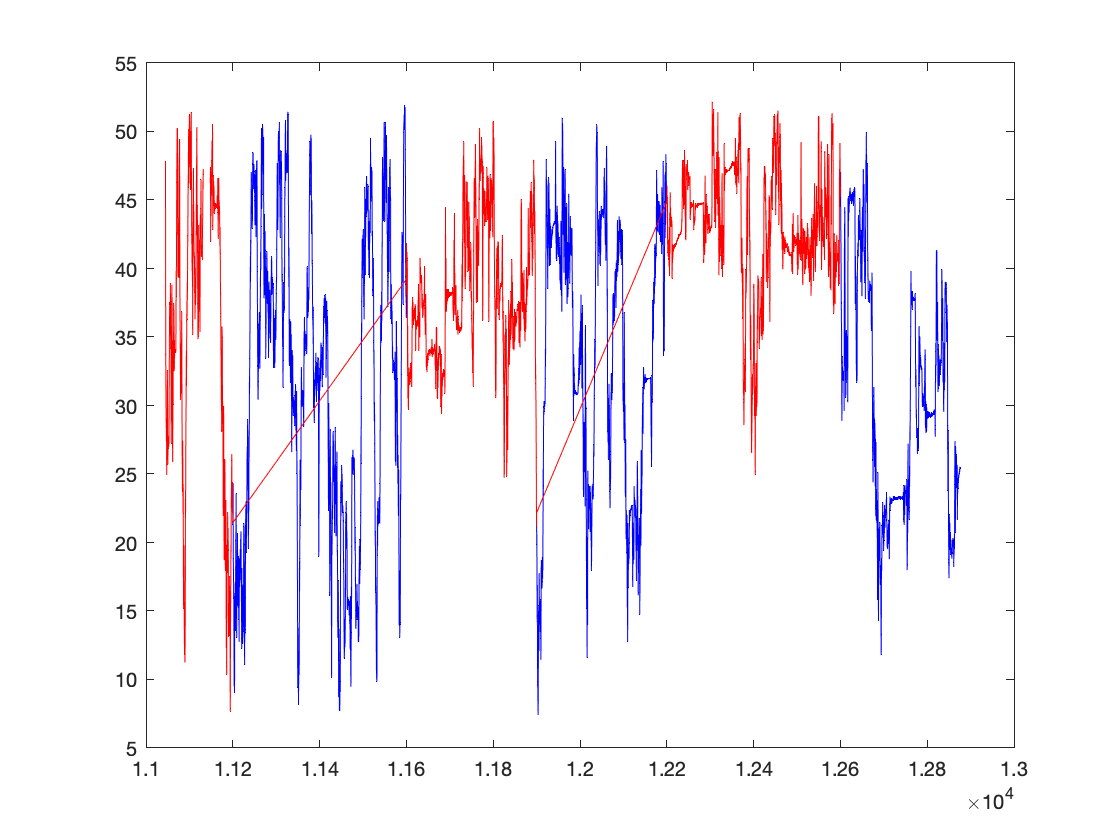


% we can plot pos.Y using the plot method
close all
p1 = Ypos_TSD.plot();
p1.Color = [0 0 1]; % blue
hold on

% restricting the data to only times when the animal is in the 
% left side of the box
newY_TSD = Ypos_TSD.Restrict(in_left_IS);
p2 = newY_TSD.plot();
p2.Color = [1 0 0]; % red

Some TStoolbox methods will generate TSD's. For example:

length_of_ripples_TSD = ripple_IS.length()

length_of_ripples_TSD =   4192×1 tsd array with properties:

              version: 2
                    t: [4192×1 double]
               t_info: 'time points'
                 data: [4192×1 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''


rippleIS is an intervalSet, but the length method returns a TSD containing the duration of each ripple event

## 4) tsdArray - an object that holds an array of TS's or TSD's

- This is not a MATLAB array of TS's, it's a specialized object for holding array data

- This is what you use for a group of simultaneously recorded spike trains

- You could also use this to store numerical data in matrix format, e.g. binned spike trains or principal components. A key advantage of this is that each row of the matrix has a timestamp associated with it, and the object also contains the corresponding intervalSet

% now we'll load in some data recorded from the NAc
load NAcSpikes.mat

% NAcSpikes.S is a tsdArray holding 35 spike trains
NAcSpikes_tsdArr = NAcSpikes.S

% live script - you need to type it in the command window


NAcSpikes.S contains a cell array of TS's, each of which holds the spike train for one unit

% looking at NAcSpikes.S
C = NAcSpikes_tsdArr.C

C = 35×1 cell array
    {55561×1 ts}
    {19928×1 ts}
    {19020×1 ts}
    { 5915×1 ts}
    {24021×1 ts}
    { 7795×1 ts}
    {24336×1 ts}
    {24535×1 ts}
    {11720×1 ts}
    { 8584×1 ts}
    {40690×1 ts}
    {40339×1 ts}
    {43042×1 ts}
    {62165×1 ts}
    {54027×1 ts}
    {18084×1 ts}


C{1}

ans =   55561×1 ts array with properties:

              version: 1
                    t: [55561×1 double]
               t_info: 'spike times'
                 data: []
            data_info: []
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which spike times are defined'
                 name: 'spike train'



% let's pretend to extract just the spikes from D1+ MSNs
isMSN = rand(35,1) < 0.7 % boolean vectors, 1 if MSN, 0 if not 

isMSN = 35×1 logical array
   1
   1
   0
   0
   1
   1
   1
   1
   1
   0


isD1  = rand(35,1) < 0.5 % boolean vectors, 1 if D1, 0 if not

isD1 = 35×1 logical array
   1
   0
   0
   0
   0
   0
   0
   0
   1
   0



% here are the spikes from D1+ MSNs
D1MSN_spikes_tsdArr = NAcSpikes_tsdArr(isMSN & isD1)

% here are their firing rates
D1MSN_spikes_tsdArr.Rate() % bug: Rate() works but rate() doesn't

ans =     2.3816
    0.5026
    1.7446
    0.5384
    3.2558
    5.8653
    0.4919
    7.8370
    0.6304
    1.4676



% let's look at the firing rate of those cells during ripples
D1MSN_ripple_tsdArr = D1MSN_spikes_tsdArr.Restrict(ripple_IS)
D1MSN_ripple_tsdArr.Rate()

ans =     2.2521
    0.6492
    2.7096
    0.5565
    2.3448
    6.3456
    0.6825
    5.7561
    0.8895
    1.6162



% useful method to convert tsdArray to the buzcode spike train format
buzcode_cell_array_of_spikes = D1MSN_ripple_tsdArr.bzFormat()

buzcode_cell_array_of_spikes = 11×1 cell array
    {340×1 double}
    { 98×1 double}
    {409×1 double}
    { 84×1 double}
    {354×1 double}
    {958×1 double}
    {103×1 double}
    {869×1 double}
    {134×1 double}
    {244×1 double}
    {708×1 double}


There are a couple of relevant bugs with tsdArrays that were introduced between version 1 and version 2 that haven't been fully resolved

- in NAcSpikes.S, each TS has its own intervalSet, but it would be better if we made it so the entire tsdArray has only one intervalSet that's common to all of the elements

- Not all indexing is fully implemented in subsref(). For example, you can't get the first spike train by typing NAcSpikes.S.C{1}, but you can do it the way shown above

Now let's use a tsdArray that's a matrix of numbers. 

% this is the method for binning spike trains.
% we plan to rename it
binned_NAc_spikes_tsdArr = NAcSpikes_tsdArr.MakeQfromS(0.1)

binned_NAc_spikes_tsdArr =   233302×35 tsd array with properties:

              version: 2
                    t: [233302×1 double]
               t_info: 'time points'
                 data: [233302×35 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''



% we can get just the bins that are during ripples
binned_ripple_spikes_TS = binned_NAc_spikes_tsdArr.Restrict(ripple_IS)

binned_ripple_spikes_TS =   1466×35 tsd array with properties:

              version: 2
                    t: [1466×1 double]
               t_info: 'time points'
                 data: [1466×35 double]
            data_info: 'values at time points'
         timeInterval: [1×1 intervalSet]
    timeInterval_info: 'intervalSet over which data is defined'
                 name: ''


cd('..'); % changing back to TStoolbox base directory

## The idea with Neuroseries is to update the old TStoolbox and make it fully interchangeable with the new Python version. 